clear;
load('config.mat', "dirname", "block_Nx", "block_Ny");
% dirname = '.\20200421T231105\'; % 10 * 10
% dirname = '.\20200423T232037\'; % 10 * 10 noise
% dirname = '.\20200424T212550\';  % 5 * 10 noise
% dirname = '.\20200424T214617\';  % 5 * 6  noise
% block_Nx = 5;
% block_Ny = 10;
% dirname = '.\20200426T191014\'; % 6 * 9  noise
tagPath = dirname;


## 循环读取 12 个 beacon 的数据

N_beacon = 12;
beacon = 0;

for i=1:N_beacon
    filename = sprintf('%s%s%d.mat', tagPath, 'Beacon_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    
    if i == 1
        beacon = [Amp_1 An_diff];
    else
        beacon = [beacon; Amp_1 An_diff];
    end
end


## 循环读取 tag 的数据, 计算距离

N_tag = block_Nx * block_Ny;
tag = 0;

for i=1:N_tag
    filename = sprintf('%s%s%d.mat', tagPath, 'sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    tag = [Amp_1 An_diff];

    y_sig =  [beacon;tag];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        distance = D(N_beacon + 1:end, 1:N_beacon)';
    else
        distance = [distance  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end


## 计算 tag 和 beacon 的距离

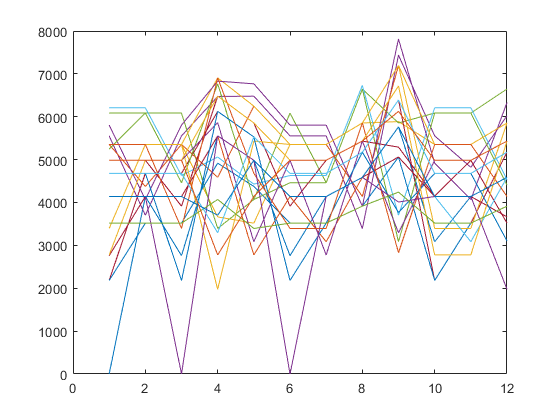

% y_sig =  [beacon;tag];
% D = pdist(y_sig);
% D = squareform(D);
% distance = D(N_beacon + 1:end, 1:N_beacon)';

% 12 * XXX
figure;plot(distance);

%% 保存
filename = sprintf('%s%s.mat', tagPath, 'distance');
save(filename, 'distance');

## 读取房内和房外的数据

load('.\DataSet\sample.mat', "N_inside", "N_outside");
ioPath = '.\DataSet\';

% inside
y_in = 0;
for i=1:N_inside
    filename = sprintf('%s%s%d.mat', ioPath, 'i_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    y_in = [Amp_1 An_diff];
    
    y_sig =  [beacon;y_in];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_in = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_in = [dist_in  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

% outside
y_out = 0;
for i=1:4*N_outside
    filename = sprintf('%s%s%d.mat', ioPath, 'o_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    y_out = [Amp_1 An_diff];
    
    y_sig =  [beacon;y_out];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_out = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_out = [dist_out  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

## 计算内外样本点和 beacon 的距离

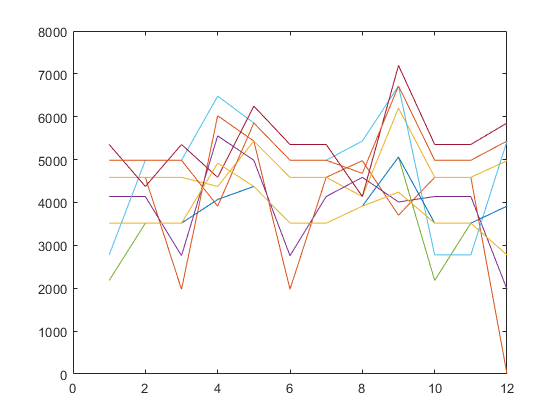

% y_io = [beacon ; y_in ; y_out];
% D_io = pdist(y_io);
% D_io = squareform(D_io);
% distance_io = D_io(N_beacon + 1:end, 1:N_beacon)';
% figure;plot(distance_io(:, 1:N_inside));
% figure;plot(distance_io(:, N_inside+1:end));
distance_io = [dist_in dist_out];
figure;plot(dist_in);

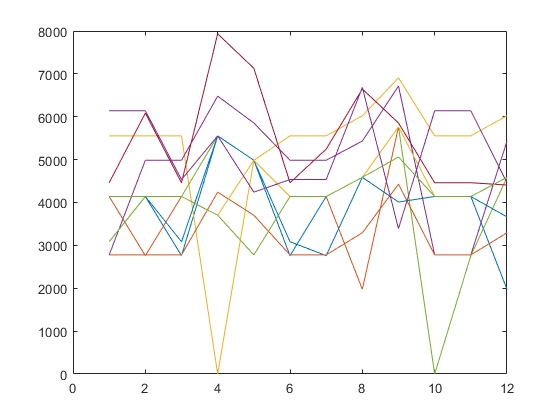

figure;plot(dist_out);

%% 保存
ioPath = '.\DataSet\';
filename = sprintf('%s%s.mat', ioPath, 'distance_io');
save(filename, 'distance_io');

## svm 数据集预处理

% 数据处理

%% 载入
filename = sprintf('%s%s.mat', tagPath, 'distance');
load(filename, 'distance');
N_tag = block_Nx * block_Ny;

load('.\DataSet\sample.mat', "N_inside", "N_outside");
ioPath = '.\DataSet\';

filename = sprintf('%s%s.mat', ioPath, 'distance_io');
load(filename, 'distance_io');

dist_in = distance_io(:, 1:N_inside);
dist_out = distance_io(:,N_inside+1:end);

% 按列打乱 dist_out
rowrank = randperm(length(dist_out(1,:)));
dist_out = dist_out(:, rowrank);

% 训练集
N_o_train = 6;
dist_train = [distance dist_out(:, 1:N_o_train)];
label_train = [ones(1, N_tag) zeros(1, N_o_train)];
% 按列打乱 dist_train label_train
rowrank = randperm(length(dist_train(1,:)));
dist_train = dist_train(:, rowrank);
label_train = label_train(:, rowrank);

% 测试集
N_o_test = 4*N_outside - N_o_train;
dist_test = [dist_in dist_out(:, N_o_train+1:end)];
label_test = [ones(1, N_inside) zeros(1, N_o_test)];
% 按列打乱 dist_test label_test
rowrank = randperm(length(dist_test(1,:)));
dist_test = dist_test(:, rowrank);
label_test = label_test(:, rowrank);

## SVM 分类

svm_x = dist_train';
svm_y = label_train;
SVMModel = fitcsvm(svm_x, svm_y, 'Standardize',true);
% 100 * 1
label_pre = predict(SVMModel, dist_test');

label_sum = label_test' + label_pre;
N_wrong = sum(label_sum(:)==1);
rate = 1- N_wrong / length(label_sum);
disp(rate);

    0.5625




wrong = find(label_sum == 1);
disp(wrong');

     1     2     4     5     9    14    16



pre_wrong = [label_test(wrong) ; label_pre(wrong)']

pre_wrong =      0     0     0     0     0     0     1
     1     1     1     1     1     1     0
